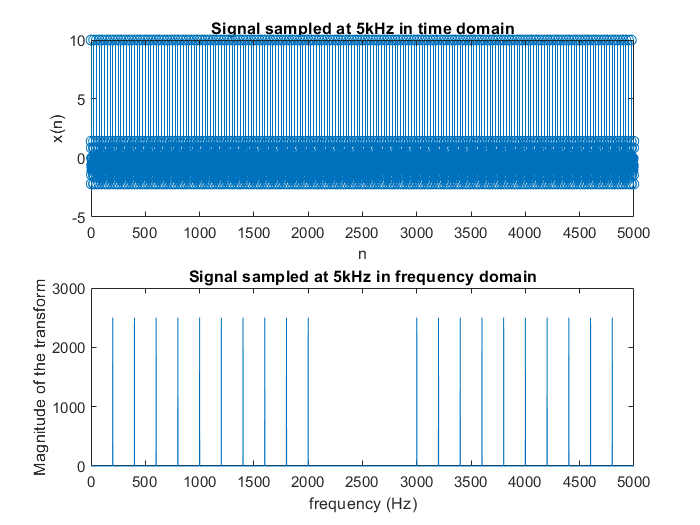

clear all;
close all;
clc;

f = 200; % Signal fundamental frequency of 200Hz.
fs= 5000; % Sampling frequency of 5kHz.
N = 5000; % Since duration of the signal is 1s, and fs=5kHz, we need 5000 samples.
n = 0:N-1;
T= 1/fs; % Sample period.
x = zeros(10,5000); % Matrix for the whole signal
for i = 1:10
    x(i,:) = cos(2*pi*i*f*n*T);
end

signal_superposition = sum(x, 1);
% Plot the orignal signal in time domain.
subplot(2,1,1);
stem(n, signal_superposition);
xlabel('n');
ylabel('x(n)');
title(['Signal sampled at 5kHz in time domain']);
% soundsc(signal_supersition);

% Plot the original signal in frequency domain.
fft_for_signal = fft(signal_superposition);
f = 0:4999;
subplot(2,1,2);
plot(f, abs(fft_for_signal));
xlabel('frequency (Hz)');
ylabel('Magnitude of the transform');
title('Signal sampled at 5kHz in frequency domain');
hold off;

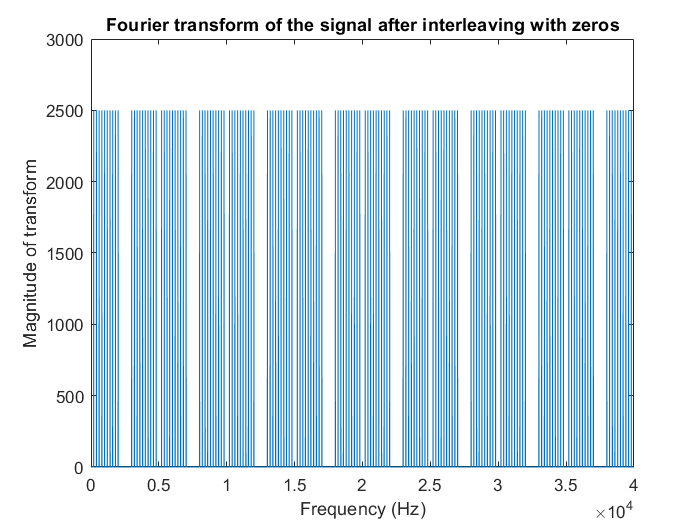

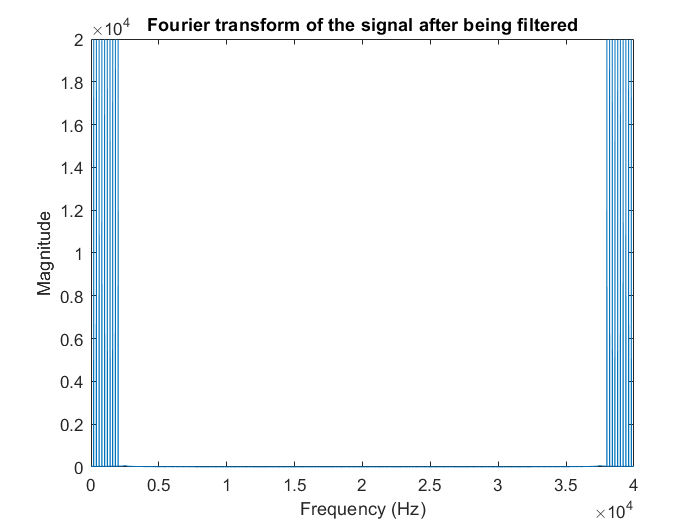

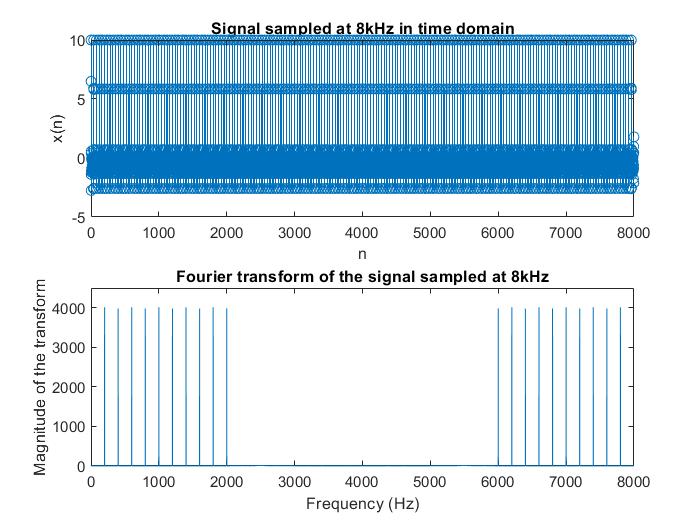

% Call the function to resample the signal to 8kHz.
Resample_5kHz_to_8kHz(signal_superposition);

function output_signal = Resample_5kHz_to_8kHz(input_signal)
% Output:
%       output_signal: The signal after being resampled.
% Input:
%       input_signal: Data for the input signal.   
% This function will resample the required signal of 5kHz with duration 1
% second to 8kHz with duration 1 second.
% The anti-aliasing operation is done with a rectangular window, which
% corresponds to a sinc function in time domain, I chose the length of the
% sinc function to be 601.
% Author: Yuchen MU
% Last modified date: 15/10/19

% ----------------------------------------------------------------
% Up-sampling part.
signal_interleave_with_zeros = zeros(1, 40000);
% Add 7 zeros between two samples.
index = 1;
for i = 1:40000
    if mod(i, 8) == 1
        signal_interleave_with_zeros(i) = input_signal(index);
        index = index + 1;
    end
end
fft_for_signal_interleave_with_zeros = fft(signal_interleave_with_zeros);
f = 0:39999;
figure
plot(f, abs(fft_for_signal_interleave_with_zeros));
xlabel('Frequency (Hz)');
ylabel('Magnitude of transform');
title('Fourier transform of the signal after interleaving with zeros');
hold off;

% ----------------------------------------------------------------
% Anti-aliasing part.
% Filter out any frequency components higher than 2.5kHz (half of the
% original sampling frequency), by applying a rectangular window, which
% corresponds to a sinc function in time domain.
% length of the sinc function is 601 points.
t = -300*(1/40000):(1/40000):300*(1/40000);
filter_sinc = sinc(5000*t);
% Convolve with sinc function in time domain, which equals to multiply with
% a rectangular window in frequency domain.
signal_after_filtering = conv(signal_interleave_with_zeros, filter_sinc, 'same');
% Plot the signal in frequency domain after being filtered.
figure
k = 0:39999;
fft_after_conv = fft(signal_after_filtering);
plot(k, abs(fft_after_conv));
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('Fourier transform of the signal after being filtered');


% ----------------------------------------------------------------
% Down-sampling part.
% Decimation operation.
signal_after_downsampling = zeros(1, 8000);
index = 1;
% Take one sample out of each 5 samples.
for i = 1:40000
    if mod(i, 5) == 1
        signal_after_downsampling(index) = signal_after_filtering(i);
        index = index + 1;
    end
end
% Plot the signal after being resampled in time domain.
k = 0:7999;
figure
subplot(2,1,1);
stem(k, signal_after_downsampling);
xlabel('n');
ylabel('x(n)');
title('Signal sampled at 8kHz in time domain');
% Plot the signal after being resampled in frequency domain.
fft_for_signal_after_downsampling = fft(signal_after_downsampling);
subplot(2,1,2);
plot(k, abs(fft_for_signal_after_downsampling));
xlabel('Frequency (Hz)');
ylabel('Magnitude of the transform');
title('Fourier transform of the signal sampled at 8kHz');
ylim([0 4500]);
% soundsc(signal_after_downsampling);
output_signal = signal_after_downsampling;
end

